% Training
filename = "";
imdsASL = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsASL =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0006.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0241.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train\A\A_0246.JPG'
                               ... and 597 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Train'
                              }
                      Labels: [A; A; A ... and 597 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     R

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:26        0.001                            4.1494
            1        1       00:00:27        0.001          4.1317                  
           10        4       00:04:18        0.001        0.044952            1.2326
           20        7       00:08:48        0.001       0.0090718           0.49989
           30       10       00:13:18        0.001       0.0013971           0.30748
           40       14       00:17:47        0.001      0.00053738           0.26846
           45       15       00:20:02        0.001      0.00033035           0.26497
Training stopped: Max epochs completed


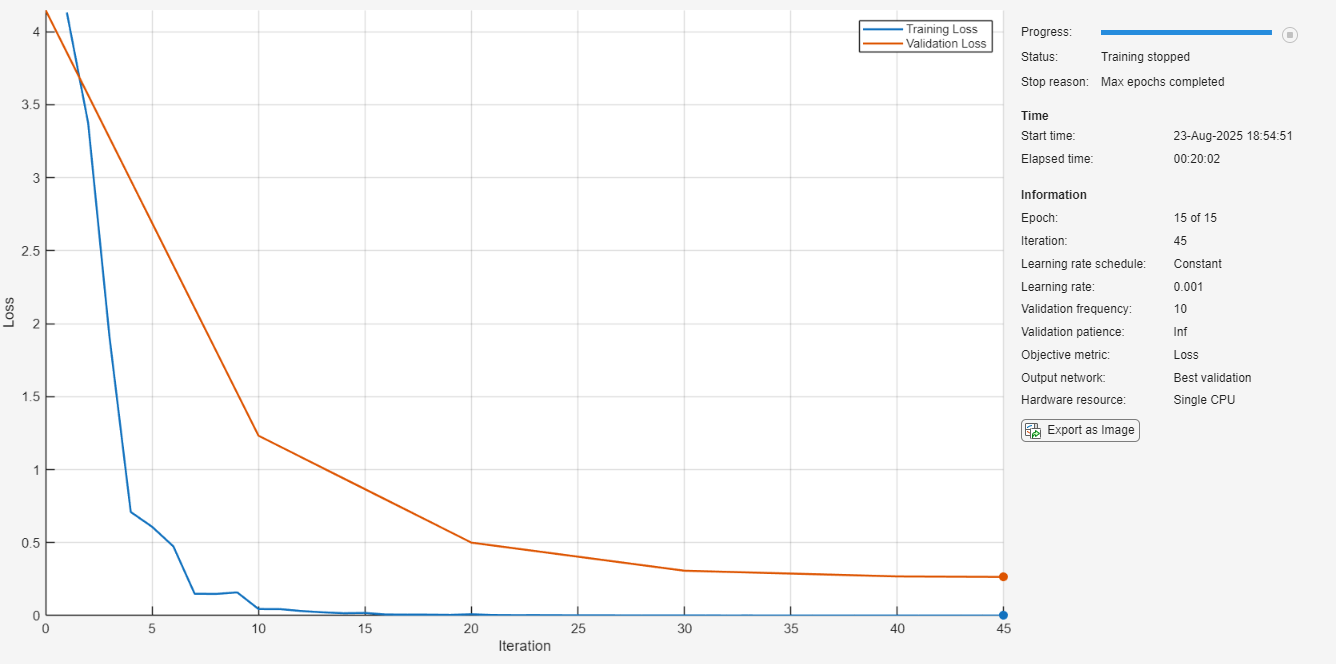

resnet18ASL =   dlnetwork with properties:

         Layers: [70×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]
     Learnables: [82×3 table]
          State: [40×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


[imdsTrain,imdsValidation] = splitEachLabel(imdsASL,0.8,"randomized");

resnet18 = imagePretrainedNetwork("resnet18","NumClasses",24);

inputSize = resnet18.Layers(1).InputSize;
augTrain = augmentedImageDatastore(inputSize,imdsTrain);
augVal = augmentedImageDatastore(inputSize,imdsValidation);

opts = trainingOptions("adam",ValidationData=augVal,Shuffle="every-epoch", ...
    Plots="training-progress",MaxEpochs=15,OutputNetwork="best-validation", ...
    ValidationFrequency=10,MiniBatchSize=160);

resnet18ASL = trainnet(augTrain,resnet18,"crossentropy",opts)

% Evaluate model
filename = "";
imdsTest = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Test\A\A_0003.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Test\A\A_0724.JPG';
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Test\A\A_1488.JPG'
                               ... and 237 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Test'
                              }
                      Labels: [A; A; A ... and 237 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Read

augTest = augmentedImageDatastore(inputSize,imdsTest);

classNames = categories(imdsTest.Labels);
testPreds = minibatchpredict(resnet18ASL,augTest);
testPredClass = scores2label(testPreds,classNames);

testAccuracy = nnz(testPredClass == imdsTest.Labels)/length(testPredClass)

testAccuracy = 0.9208

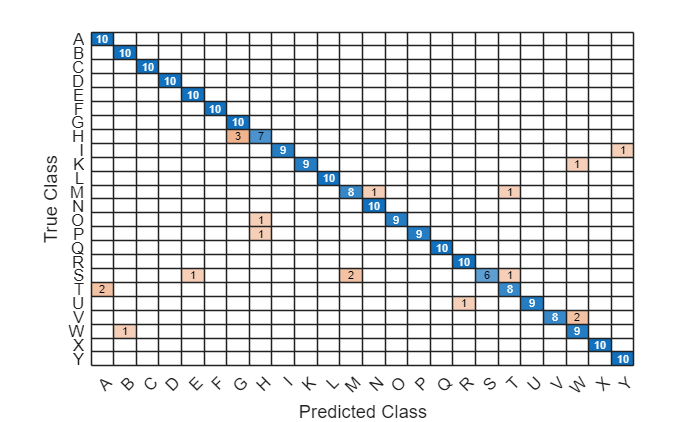

confusionchart(imdsTest.Labels,testPredClass)